**SimpleSharpRange.mlx is a Sharp IR sensor calibration center.**

It is an example of reading an analog sharp IR range sensor on an Arduino.

Connect analog out from the sensor into Pin A0, Vcc to 5V DC, gnd to gnd.

Jack Levitsky and CJ Hilty, April 2022, Rev. #A.

clc;            %clear command window
clear;          %clear MATLAB workspace

**Set up robot control system **(code that runs once)

[m] = input("When all targets are removed from area and backdrop is perpendicular, press ENTER.");

[robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('COM12'); % COM8 for Jack, COM12 for CJ
beep;

%Configure test loop to collect n data points
nTests = input(['Enter number of range test positions, then hit enter']);
clc;

%Create a variable to hold experimental position data
positionData=zeros(nTests,2);

r=rateControl(1);  %1hz loop rate control object created
reset(r);          %reset loop time to 0


**Run robot control loop **(code that runs over and over)

 controlFlag = 1;           %create a loop control
 while (controlFlag <= nTests)  
    rangeData=SENSE(robotArduino, rawRangeIn);
    THINKdistanceIR(rangeData); %Calculates distance to targets
    ACT();  %Command robot actuators
% 
%         positionData(controlFlag,1)=input("enter actual distance (cm)" );
%         gtest=input("Point IR at new range, type G, then hit enter ","s");
%         positionData(controlFlag,2)=rangeData;
%         Blink(robotArduino,blinkLED,1);

        waitfor(r);         %wait for loop to complete
        controlFlag=controlFlag+1;
 end

### **Mission data processing**

This code will allow up to plot measured versus actual range positions.

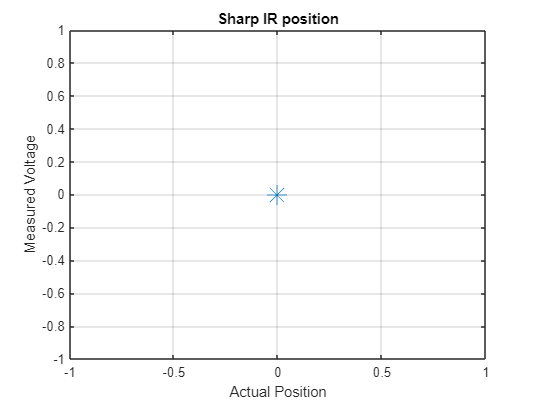

plot(positionData(:,1), positionData(:,2),'-*', MarkerSize=15);
grid on;
xlabel("Actual Position")
ylabel("Measured Voltage")
title("Sharp IR position")

### **Clean shut down**

clc
clear robotArduino

**Robot Functions** (store the code's local functions here)

To make things readable, modular, and reusable, your main robot code is as brief as possible while the majority of work is completed by functions

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot
% controller. Inputs: COM port for the arduino. Returns: Ardunio system
% object called robotArdunio, pan servo system object, tilt servo system object and LED system object.
% Pair Programmed by Jack and CJ 2022.


% Create a global arduino object so that it can be used in functions
% a = arduino('setTOYourComNumber','Uno','Libraries,'Servo');
    robotArduino = arduino(COMPORT,'Uno','Libraries','Servo');

% configure pin 13 as digital-out LED
    blinkLED = 'D13';
    configurePin(robotArduino,blinkLED,'DigitalOutput');

% configure pins A1-A5 as analog inputs
    rawRangeIn=['A1'; 'A2'; 'A3'; 'A4'; 'A5'];
    configurePin(robotArduino,rawRangeIn(1,:),'AnalogInput');
    configurePin(robotArduino,rawRangeIn(2,:),'AnalogInput');
    configurePin(robotArduino,rawRangeIn(3,:),'AnalogInput');
    configurePin(robotArduino,rawRangeIn(4,:),'AnalogInput');
    configurePin(robotArduino,rawRangeIn(5,:),'AnalogInput');
end

function [] = Blink(a,LED,n)
    % Blink toggles Arduino a LED on and off to indicate program running
    % input n = number of blinks
    % no output is returned
    % Jack and CJ 2022
    for bIndex = 1:n
        writeDigitalPin(a,LED,0);
        pause(0.3)
        writeDigitalPin(a,LED,1);
        pause(0.3)
    end
end

**Sense Functions **(store all sense related functions here)

function rangeData = SENSE(robotArduino, rawRangeIn)
% disp('sense');
rangeData=zeros(1,length(rawRangeIn)); %row vector

    for i=1:length(rawRangeIn)
    rangeData(:,i)=readVoltage(robotArduino,rawRangeIn(i,:)); %store each distance as part of row vector
    end

end

**Think Functions **(store all think related functions here)

function THINK()
%disp('think');
end

function [distances]=THINKdistanceIR(voltages,target_color)
% [distances]=readSharpIR(voltages,target_color).
% supported target_color values: 1, black.
%readSharpIR takes a set of analog pin voltages from 5 Sharp Infared sensors and
%based on calibration performed on 4 April 2022, converts the voltages to
%a vector of approximate distances.
% Inputs: voltages is a row vector of 5 voltages for each of the analog
% output readings of the IR sensors in the array.
% target_color is the color of the target because calibration can vary by target
% color. Check above for the supported values of target_color.
% The calibration is accurate from ~18 cm to ~31 cm.
% for voltages outside of the range 0.3 to 0.75 volts, the function will
%output a zero to indicate that the calibration sequence does not map
% to any points in the reliable range.

if nargin <2 % Deal with potential lack of target_color input
    target_color=1; % default to coefficients for black background
end

distances = zeros(1,5);

a=1; %As target types increase, increase A to include more coefficients
coefficients = zeros(5,4,a); %create blank coefficients matrix

coefficients(:,:,1) =...
    [-443.7 867.3 -581.3 150.8;...
    -1225 2269 -1408 313.5;...
    -67.25 164.7 -154.8 67.36;...
    -284.3 507.8 -339.6 102.2;...
    -76.67 220.1 -196.3 73.82]; %each row is a single set of coefficients for a sensor.
% all 4 coefficients go to that of a 3rd-degree polynomial

%Store distances by applying coefficients for the 3rd-degree polynomial
for i=1:length(voltages)
    if (voltages(i)>=0.75) || (voltages(i)<=0.3) %if outside of reliable range
        distances(1,i)=0; %set distance to zero
        continue
    end
    V_power=[voltages(i).^3;voltages(i).^2;voltages(i);1];
    distances(1,i) = coefficients(i,:,a)*V_power;
end

end

**Act Functions **(store all act related functions here)

function ACT(time)
%disp('act');
end